# Aula Prática 3

Aluno 1

Aluno 2

## Exercício 1

Calcule a DFT do sinais e mostre sua magnitude e fase para os valores de $N$indicados e compare com o resultado para $N=1024$. Comente os resultados.

### a) $$x[n] = \cos\left(\pi \frac{n}{N} \right) + \sin^{2} \left(\pi \frac{n}{N} \right)$, para$ $0 \leq n \leq 10$ e $N = 11$

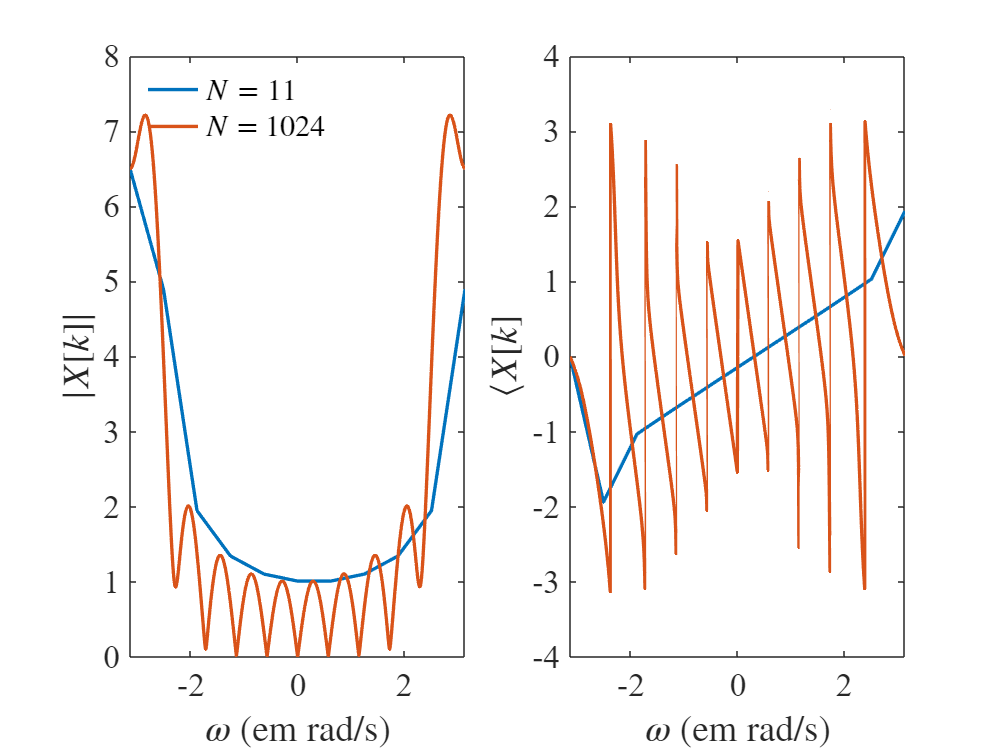

N_1 = 11;
N_2 = 1024;

n = 0:N_1-1;

x = cos(pi*n/N_1) + sin(pi*n/N_1).^2;

X1 = fft(x,N_1);
X2 = fft(x,N_2);

frequency_1 = 2*pi*linspace(-0.5,0.5,N_1);
frequency_2 = 2*pi*linspace(-0.5,0.5,N_2);

plotSpectrum(frequency_1,X1,frequency_2,X2,N_1);

### Comentários

### b) $$x[n] = \mathrm{e}^{-2n}$, para $0 \leq n \leq 20$$

### Comentários

### c) $$\delta[n-1]$, para $0 \leq n \leq 2$$

### Comentários

### d) $$x[n] = n$, para $0 \leq n \leq 5$$

## Funções

function plotSpectrum(frequency_1,X1,frequency_2,X2,N_1)

figure;

set(gcf,'position',[0 0 800 600]);

subplot(1,2,1);

plot(frequency_1, abs(X1),'linewidth',2);
hold on;
plot(frequency_2, abs(X2),'linewidth',2);

xlabel('$\omega$ (em rad/s)','fontname','times new roman','fontsize',20,'interpreter','latex');   % Texto do exio x
ylabel('$|X[k]|$','fontname','times new roman','fontsize',20,'interpreter','latex');              % Texto do eixo y

set(gca,'fontname','times new roman','fontsize',20);                                              % Ajustando a fonte e o tamanho do nos eixos

legend({['$N = ' num2str(N_1) '$'],'$N$ = 1024'}, 'interpreter', 'latex','location','northwest'); % Criando a legenda da figura
legend boxoff

subplot(1,2,2);

plot(frequency_1, angle(X1),'linewidth',2);
hold on;
plot(frequency_2, angle(X2),'linewidth',2);

xlabel('$\omega$ (em rad/s)','fontname','times new roman','fontsize',20,'interpreter','latex');   % Texto do exio x
ylabel('$\langle X[k]$','fontname','times new roman','fontsize',20,'interpreter','latex');        % Texto do eixo y

set(gca,'fontname','times new roman','fontsize',20);                                              % Ajustando a fonte e o tamanho do nos eixos
end